clear
close all
clc

s = tf('s');

g = 9.82;
l_P = 1;
M_L = 2.941;
M_T = .792;
M_H = .951;
M_TL = M_L+M_H;
I_x = 0.2;
r_x = .075;
M_1 = M_T+M_L+M_H+I_x/r_x^2;
B_x = 13.4;
N_x = 48/12*72/14;
k_e = 0.609e-3;

G_x = s*(s^2+g/l_P)/(s^3*(M_1-M_TL)+s^2*B_x+s*M_1*g/l_P +B_x*g/l_P)

G_x =
 
               s^3 + 9.82 s
  --------------------------------------
  36.35 s^3 + 13.4 s^2 + 395.2 s + 131.6
 
Continuous-time transfer function.



G_x_poles = pole(G_x)

G_x_poles =   -0.0176 + 3.2954i
  -0.0176 - 3.2954i
  -0.3334 + 0.0000i


G_x_zeroes = zero(G_x)

G_x_zeroes =    0.0000 + 0.0000i
   0.0000 + 3.1337i
   0.0000 - 3.1337i


G_x_Gain = dcgain(G_x)

G_x_Gain = 0


G_theta = l_P^-1*(s^2)/(s^2+g/l_P)

G_theta =
 
     s^2
  ----------
  s^2 + 9.82
 
Continuous-time transfer function.



G_theta_zeros = zero(G_theta)

G_theta_zeros =      0
     0


G_theta_poles = pole(G_theta)

G_theta_poles =    0.0000 + 3.1337i
   0.0000 - 3.1337i


G_theta_Gain = dcgain(G_theta)

G_theta_Gain = 0

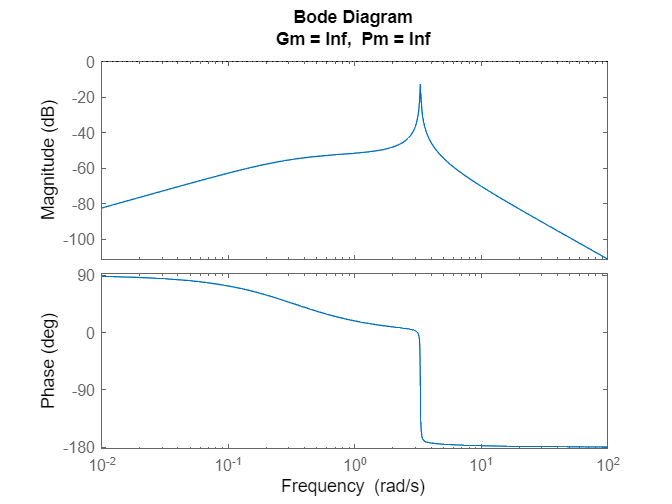

%%%
OLtheta = 1*G_x*G_theta*1/(s^2);
margin(OLtheta)

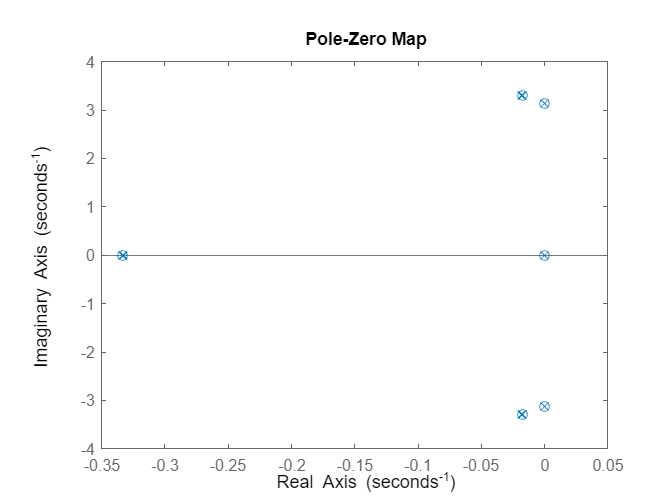


CLtheta = OLtheta/(1+OLtheta);
pzmap(CLtheta)

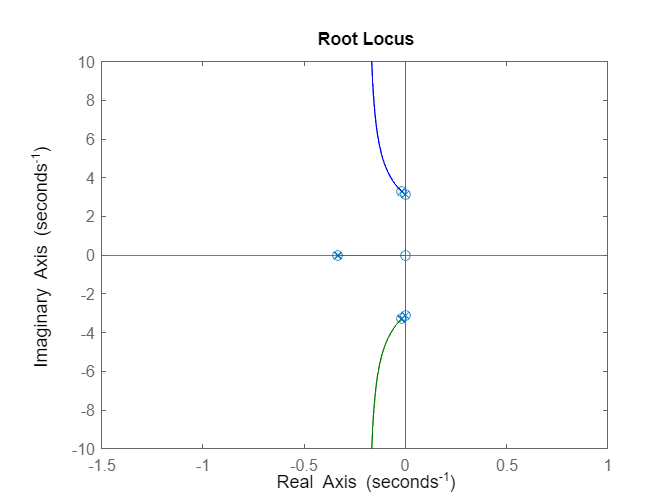

rlocus(CLtheta)

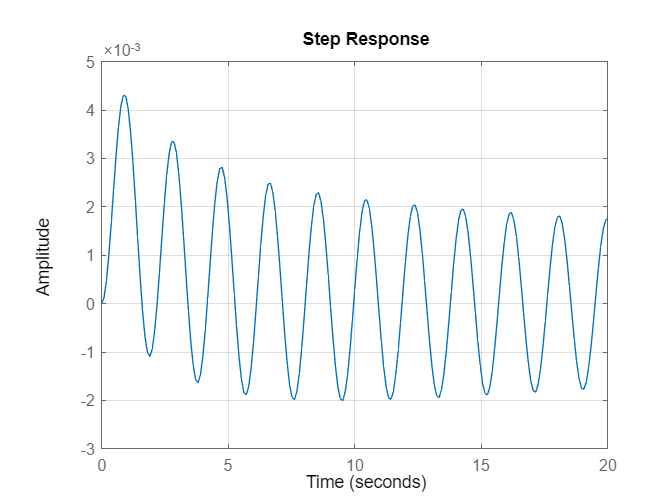

step(CLtheta, 20)
grid on

thetaPerIxCL = -1*G_x*G_theta*s^(-2)/(1+G_x*G_theta*s^(-2))

thetaPerIxCL =
 
                                                                                                    
    -36.35 s^12 - 13.4 s^11 - 1109 s^10 - 394.8 s^9 - 1.127e04 s^8 - 3877 s^7 - 3.811e04 s^6        
                                                                                                    
                                                                                      - 1.269e04 s^5
                                                                                                    
  ----------------------------------------------------------------------------------------------------
                                                                                                      
  1321 s^14 + 974.1 s^13 + 5.489e04 s^12 + 3.93e04 s^11 + 8.559e05 s^10 + 5.942e05 s^9 + 5.952e06 s^8 
                                                                                                      
                                         + 3.99e06 s^7 + 1.578e07 

pzmap(thetaPerIxCL)

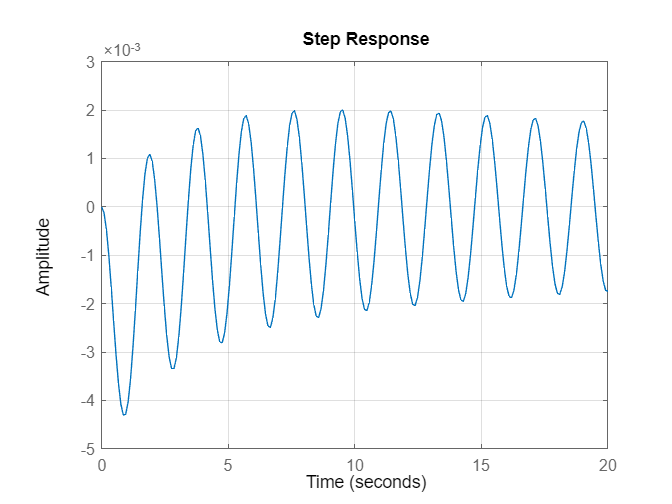

step(thetaPerIxCL,20)
grid on